数据导入

close all
clear

dataDir = 'D:/Phd Research/MRI_Data/data1_results_wu_241105/';
patientname = 'WANG_HUI_13146665/';
patientDir = [dataDir,patientname];
TE=[60 80 100 120 140];
B=[0 200 500 1000 1500 2000];
num_TE=length(TE);
num_B=length(B);

IMG=zeros(184,180,num_TE,num_B);
for i=1:num_TE
    DWIfile = ['DWI_6B_TE',num2str(TE(i)),'AP'];
    DWIoriginalNII = load_untouch_nii([patientDir,DWIfile,'/',DWIfile,'_topup.nii']);
    DWIoriginalimg = double(DWIoriginalNII.img);
    IMG(:,:,i,:)=DWIoriginalimg(:,:,9,:);
end

size(IMG)

ans =    184   180     5     6


img_layer_9=[[IMG(1:170,:,1,1),IMG(1:170,:,1,2),IMG(1:170,:,1,3),IMG(1:170,:,1,4),IMG(1:170,:,1,5),IMG(1:170,:,1,6)];
    [IMG(15:170,:,2,1),IMG(15:170,:,2,2),IMG(15:170,:,2,3),IMG(15:170,:,2,4),IMG(15:170,:,2,5),IMG(15:170,:,2,6)];
    [IMG(15:170,:,3,1),IMG(15:170,:,3,2),IMG(15:170,:,3,3),IMG(15:170,:,3,4),IMG(15:170,:,3,5),IMG(15:170,:,3,6)];
    [IMG(15:170,:,4,1),IMG(15:170,:,4,2),IMG(15:170,:,4,3),IMG(15:170,:,4,4),IMG(15:170,:,4,5),IMG(15:170,:,4,6)];
    [IMG(15:end,:,5,1),IMG(15:end,:,5,2),IMG(15:end,:,5,3),IMG(15:end,:,5,4),IMG(15:end,:,5,5),IMG(15:end,:,5,6)]];
size(img_layer_9)

ans =          808        1080


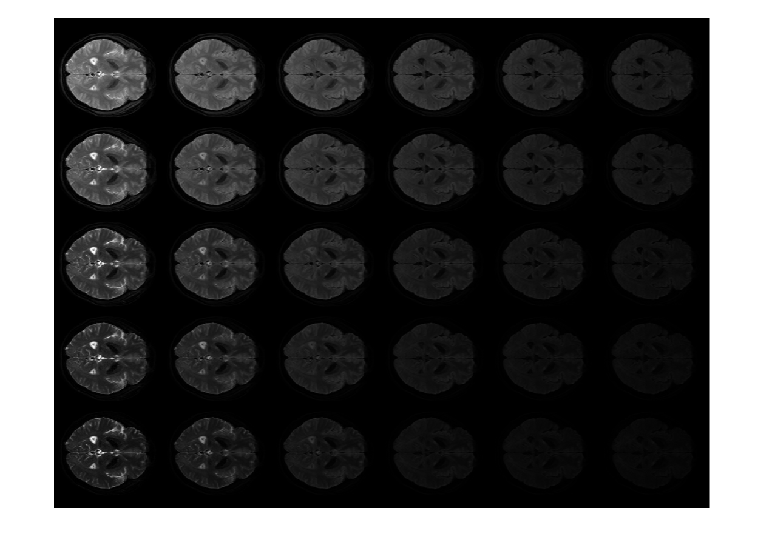

close all
imshow(img_layer_9/500.0)

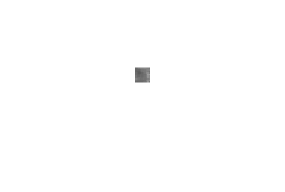

close all
temp=squeeze(IMG(81:90, 51:60, 1, 1));
imshow(temp/500.0)

ROI_te=IMG(81:90, 51:60, :, 1);
ROI_b=IMG(81:90, 51:60, 1, :);
ROI_b=reshape(ROI_b,10*10,[]);
ROI_te=reshape(ROI_te,10*10,[]);
ROI_b=ROI_b';
ROI_te=ROI_te';
size(ROI_b)

ans =      6   100


size(ROI_te)

ans =      5   100


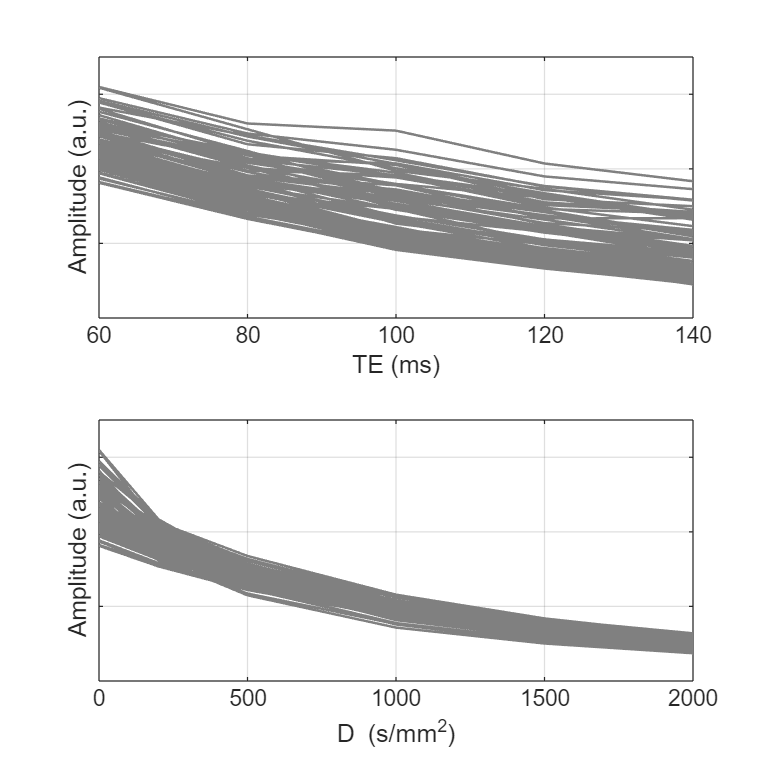

fig=figure('Position',[520,480,700,700]);
subplot(2,1,1)
plot(TE, ROI_te(:,:),"Color",'[0.5, 0.5, 0.5, 0.9]','LineWidth',1)
ylim([0,350])
set(gca, 'yticklabel', [])
xlabel('TE (ms)')
ylabel('Amplitude (a.u.)')
grid on; % 添加网格

subplot(2,1,2)
plot(B, ROI_b(:,:),'Color','[0.5, 0.5, 0.5, 0.9]','LineWidth',1)
ylim([0,350])
set(gca, 'yticklabel', [])
xlabel('D (s/mm^2)')
ylabel('Amplitude (a.u.)')
grid on; % 添加网格